## Question 1:

t = -10:0.01:10;
x = double(heaviside(t));
h = double(exp(-t).*(t>0));


function y_manual = computeConv(t, x, h)
    %define dt
    dt = 0.01;
    %Flip x
    x_flipped = fliplr(x);
    %Compute the lengths of x and h
    L_x = length(x_flipped);
    L_h = length(h);
    %Pad h
    h_pad = [zeros(1,L_x-1), h, zeros(1,L_x-1)];
    %Initialize y_manual, recall it has size = sum of lengths of h and x -1.
    L_y = L_h + L_x - 1;
    y_manual = zeros(1,L_y);
    
    % Slide x_flipped across h_pad
    for i = 1:L_y
        y_manual(i) = sum(x_flipped.*h_pad(i:i+L_x-1))*dt; %compute summed product and mult by dt as its an integral
    end
    
    %Define time vector corresponding to y
    t_y = linspace(t(1)+t(1), t(end)+t(end), L_y); %Think about why it is not the same as 't'

    %Plotting time
    figure;

    subplot(2,2,1);
    plot(t,x);
    title("x(t)");

    subplot(2,2,2);
    plot(t,h);
    title("h(t)");

    subplot(2,2,3);
    plot(t,x_flipped);
    title("Flipped x(t)");
    
    subplot(2,2,4);
    plot(t_y,y_manual);
    title("y(t) = x(t)*h(t)");
    xlim([-10,10]);
end

%y = computeConv(t,x,h);

Question 2:

%ICs and constants:
Vc0 = 0;
R = 100;
C = 1;
tRange = [0,20];

%Define input voltage
v = @(t) sin(t);
K = 1/(R*C);

%Numerical soln
[t_num, Vc_num] = ode45( @(t,Vc)  K*(v(t) - Vc), tRange, Vc0); %numerical

%Symbolic:
syms t tau
h = K*exp(-(t-tau)*K)*heaviside(t-tau);
v = sin(tau)*heaviside(tau);
Vc_sym = simplify(int(h*v, tau, 0, t));
Vc_sym_vals = double(subs(Vc_sym, t, t_num)); %plug in
difference = Vc_num - Vc_sym_vals;

%figure
%subplot(2,1,1);
%plot(t_num, Vc_num, 'b', 'LineWidth', 1.3)
%title("ode45 Solution")
%subplot(2,1,2);
%plot(t_num, Vc_sym_vals, 'r--', 'LineWidth', 1.3)
%title("Symbolic integration solution")
%grid on

## Question 3

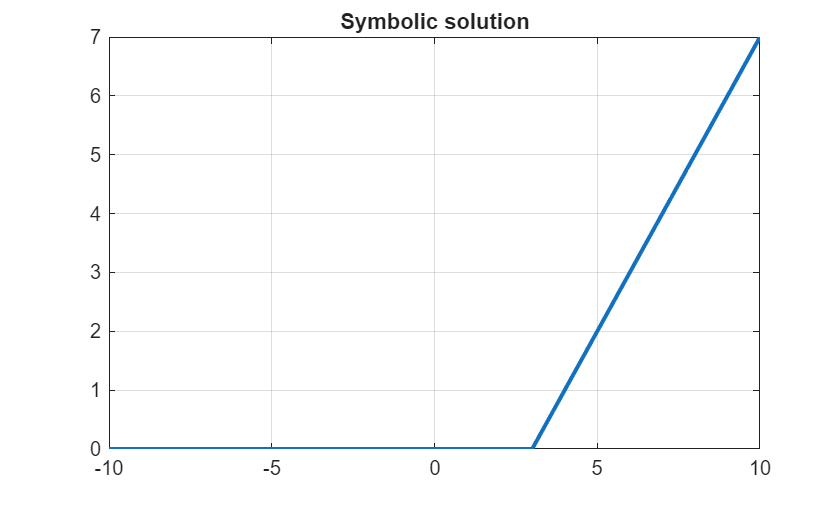

t = -10:0.01:10;
dt = 0.01;

x = double(heaviside(t-2));
h = double(heaviside(t-1));
%Properties of convolution yields y' = x'(t)h(t) = delta(t-2)u(t-1) =
%u(t-3)
syms t tau
f = heaviside(tau-3);
y_sym = int(f, tau, -inf, t);
y_sym = simplify(y_sym);

fplot(y_sym, [-10 10], 'LineWidth', 2)
title("Symbolic solution")
grid on;